# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 8-a. 민감도 함수의 이해**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr), 김준수 박사과정생

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2023a 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : 민감도 함수의 계산

다음의 연속 시간 시스템 $G_p(s)$와 이산 시간 제어기 $C^d(z)$로 구성된 폐루프 샘플 데이터 시스템을 생각해봅시다. 

$G_p(s) = \frac{1}{s + 1}$,   $C^d(z) = \frac{T}{z-1}$

num_Gp_tf = 1;
den_Gp_tf = [1 1];
Gp_tf = tf(num_Gp_tf, den_Gp_tf);
T = 0.2;
Gd_tf = c2d(Gp_tf, T, 'zoh');
num_Cd_tf = T;
den_Cd_tf = [1 -1];
Cd_tf = tf(num_Cd_tf, den_Cd_tf, T);

위의 시스템의 폐루프 전달함수 $T^d(z) = \frac{G^d(z)C^d(z)}{1+G^d(z)C^d(z)}$는 다음과 같이 계산됩니다.

Td_tf = (Gd_tf * Cd_tf)/(1 + Gd_tf * Cd_tf);
Td_tf = minreal(Td_tf)

Td_tf =
 
         0.03625
  ---------------------
  z^2 - 1.819 z + 0.855
 
샘플 시간: 0.2 seconds
이산시간 전달 함수입니다.
모델 속성


이 폐루프 시스템의 민감도 함수(sensitivity function)은 


$$S^d(z) = 1-T^d(z) = \frac{1}{1+G^d(z)C^d(z)}$$


로 구해집니다.

Sd_tf = 1 - Td_tf

Sd_tf =
 
  z^2 - 1.819 z + 0.8187
  ----------------------
  z^2 - 1.819 z + 0.855
 
샘플 시간: 0.2 seconds
이산시간 전달 함수입니다.
모델 속성


민감도 함수의 보데 선도는, MATLAB의 `bode` 함수를 이용하여 쉽게 그릴 수 있습니다.

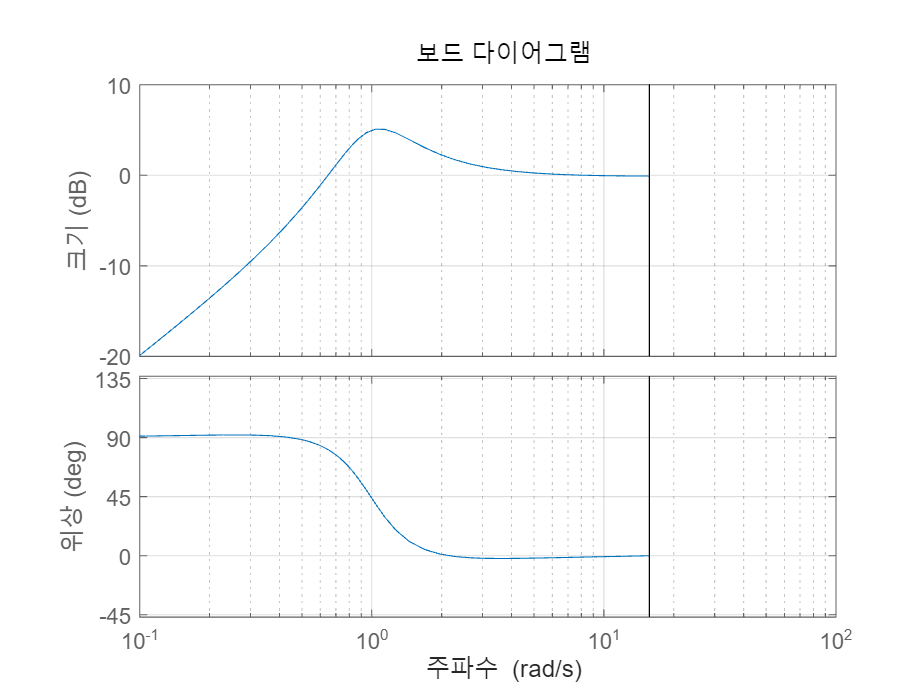

figure();
bode(Sd_tf); grid on;

### Topic 2 : 민감도 함수와 외란 제거 성능

민감도 함수는 전체 시스템의 외란 제거(disturbance rejection) 성능과 밀접한 관련이 있습니다.

이를 확인하기 위해 미리 제작해둔 다음의 slx 파일을 열어봅시다.

open('sim_topic2.slx');

slx 파일에는 다음의 폐루프 시스템이 있는데, 여기서 $G_p(s)$의 출력 $y_p(t)$에 연속 시간의 출력 외란(output disturbance)


$$d_o(t)=0.2\sin(\omega_d t)$$


가 추가로 더해져서, 제어 시스템의 전체 출력은 $y(t) = y_p(t)+d_o(t)$로 되어버린 상황입니다.

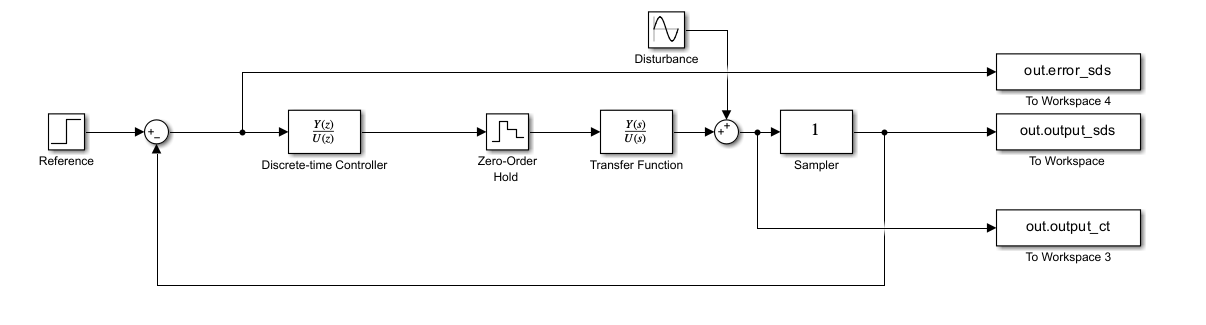

제어의 목표는, 제어 시스템의 출력인 $y(t) = y_p(t)+d_o(t)$의 샘플링 신호인 $y^d(k)=y(kT)$가 추종 신호 $r^d(k)=1$를 따라가도록 하는 것입니다. 

이 과정에서 외란 $d_o(t)$는 정확한 추종을 방해하는 요인으로 작용합니다. 

지금부터는, 주파수 영역에서 위의 시스템의 외란 제거 성능에 대해 해석해보고자 합니다. 

위의 제어 시스템에서 출력 외란과 시스템 출력 사이의 관계를 정의하는 전달함수는 민감도 함수로 계산됩니다.


$$\frac{Y^d(z)}{D_o^d(z)}=\frac{1}{1 + G^d(z)C^d(z)} = S^d(z)$$


따라서 $\omega=\omega_d$에서 민감도 함수의 크기 $|S^d(e^{j\omega T})|$가 작으면,  출력 외란이 시스템 출력 혹은 추종 성능에 적은 영향을 미친다고 결론지을 수 있습니다. 

Topic 1에서 살펴본 민감도 함수의 보데 선도를 살펴보면 다음의 결론을 얻을 수 있습니다. 

- 저주파 영역(low-frequency range)에서는 출력 외란에 대한 영향이 상대적으로 작습니다. 

- 고주파 영역(high-frequency range)에서는 $|S^d(e^{j\omega T})|$가 1에 가까우므로, 외란을 제거할 수 없습니다.

- 가운데 영역, 특히 $\omega=1~{\rm rad/s}$ 근처에서는 $|S^d(e^{j\omega T})|$가 1보다 크기 때문에 오히려 외란의 영향이 증폭됩니다(!?)

위를 확인해보기 위해 앞서 소개한 slx 파일을 이용하여 3개의 서로 다른 주파수 $\omega_d$를 이용하여 모의 실험을 해봅니다.

T_sim = 30;
dt_sim = 0.001;             

list_omega_d = {0.2, 1, 5};
list_color = {'b', 'r', 'k'};

for idx = 1:length(list_omega_d)
    omega_d = list_omega_d{idx};
    sim('sim_topic2.slx');
    simout = ans;
    time_dt_sim2{idx} = simout.time_dt;
    time_ct_sim2{idx} = simout.time_ct;
    output_ct_sim2{idx} = simout.output_ct;
    output_sds_sim2{idx} = simout.output_sds;
end

그 결과는 아래와 같습니다.

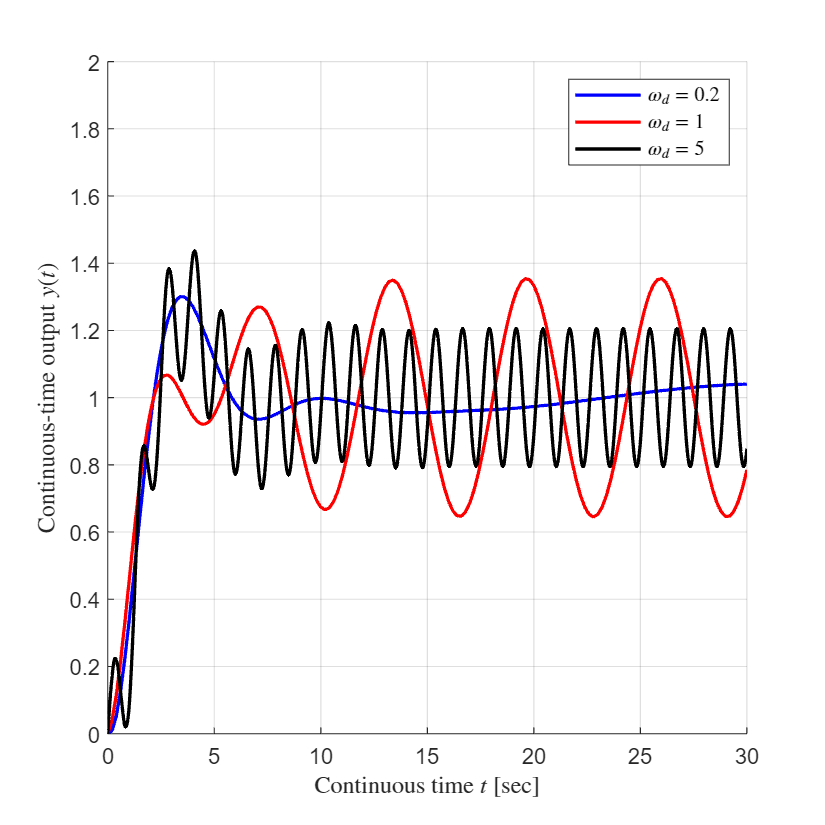

f = figure();
f.Position = [100 100 500 500];

for idx = 1:length(list_omega_d)
    hold on;
    plot(time_ct_sim2{idx}, output_ct_sim2{idx}, list_color{idx}, 'LineWidth', 1.5);        
end
grid on;
xlabel('Continuous time $t$ [sec]','Interpreter','latex');
ylabel('Continuous-time output $y(t)$','Interpreter','latex');
legend('$\omega_d = 0.2$','$\omega_d = 1$','$\omega_d = 5$','Interpreter','latex','Location','northeast'); 
xlim([0 T_sim]); 
ylim([0 2]);

모의실험 결과는 다음과 같습니다.

- $\omega_d = 0.2$ : 제어기가 저주파의 외란의 영향을 상대적으로 잘 제거합니다.

- $\omega_d = 1$ : 제어기가 외란의 영향을 정확히 제거하지 못하고, 오히려 그 크기가 증폭됩니다.

- $\omega_d = 5$ : 시스템 출력 $y(t)$가 추종값인 $1$을 기준으로 (외란 크기와 동일한) $0.2$만큼의 진폭으로 진동하고 있으며, 이로부터 외란이 제거되지 못하고 그대로 출력됨을 확인할 수 있습니다.

이는 이산 시간 출력 신호인 $y^d(k)$에서도 동일하게 확인 가능합니다.

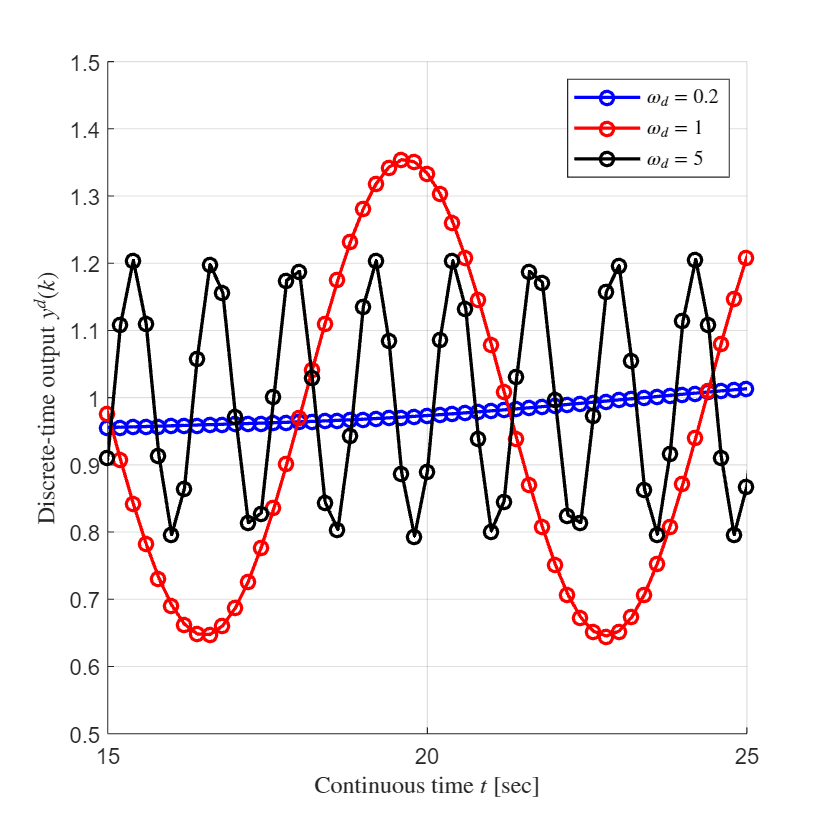

f = figure();
f.Position = [100 100 500 500];

for idx = 1:length(list_omega_d)
    hold on;
    plot(time_dt_sim2{idx}, output_sds_sim2{idx}, list_color{idx}, 'LineWidth', 1.5, 'Marker', 'O');        
end
grid on;
xlabel('Continuous time $t$ [sec]','Interpreter','latex');
ylabel('Discrete-time output $y^d(k)$','Interpreter','latex');
legend('$\omega_d = 0.2$','$\omega_d = 1$','$\omega_d = 5$','Interpreter','latex','Location','northeast'); 
xlim([15 25]); 
ylim([0.5 1.5]);

### Topic 3 : 민감도 함수의 성형과 근본적인 한계

앞에서는 민감도 함수가 외란 제거 성능과 밀접한 관련이 있음을 보였습니다. 

그렇다면 제어기를 수정하여 민감도 함수를 개선할 수는 없을까요?

결론부터 말하자면, 민감도 함수를 개선할 수는 있지만, 그만큼 공학적인 부작용이 발생합니다.

간단한 예시로 기존 제어기에서 이득값 $K_c$이 추가된 다음의 제어기를 생각해봅시다. 


$$C^d(z) = K_c \frac{T}{z-1}$$


이제 서로 다른 이득값 $K_c=0.3,~1,~3$을 가지는 3개의 제어기를 설계하고, 이에 대한 민감도 함수를 계산합니다.

Cd_tf_1 = 0.3 * Cd_tf;
Cd_tf_2 = Cd_tf;
Cd_tf_3 = 3 * Cd_tf;

Sd_tf_1 = 1/(1 + Gd_tf * Cd_tf_1);
Sd_tf_2 = 1/(1 + Gd_tf * Cd_tf_2);
Sd_tf_3 = 1/(1 + Gd_tf * Cd_tf_3);

제어기 이득이 크면 그만큼 크기가 큰 제어 입력을 만들어낼 수 있기 때문에, 제어 성능이 전반적으로 좋아지리라고 기대해볼 수 있습니다.

이를 확인해보기 위해 3개의 민감도 함수의 보데 선도를 하나의 그림으로 겹쳐서 그려봅시다.

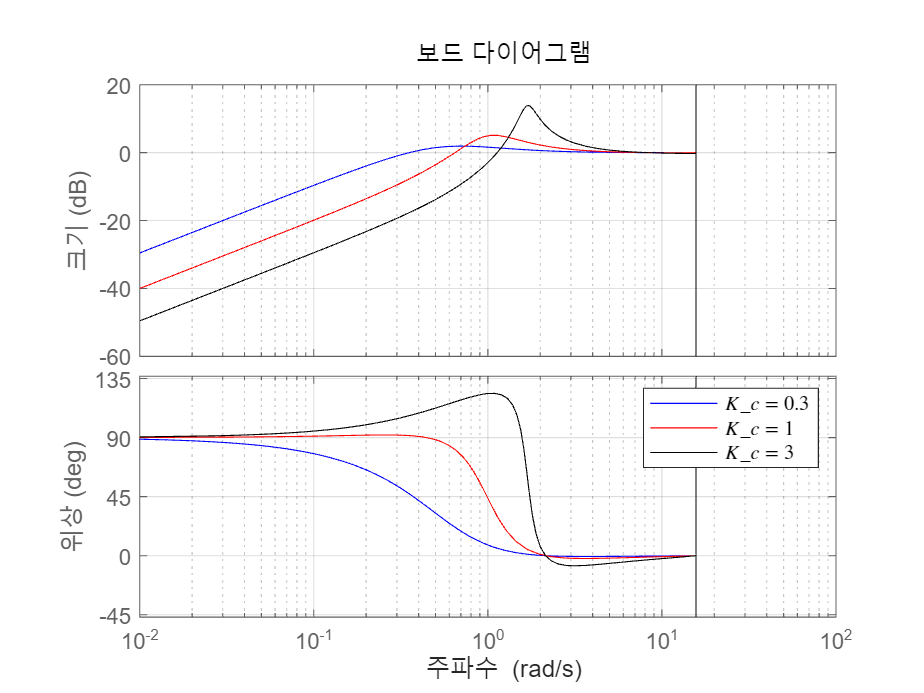

figure();
bode(Sd_tf_1, list_color{1});  hold on;
bode(Sd_tf_2, list_color{2});  hold on;
bode(Sd_tf_3, list_color{3});  grid on;
legend('$K_c = 0.3$','$K_c = 1$','$K_c = 3$','Interpreter','latex','Location','northeast'); 

위의 그림에서는 다음의 사실을 얻을 수 있습니다. 

- 제어기 이득 $K_c$이 커질수록 저주파 영역에서 외란 제거 성능이 크게 개선됩니다. 

- 하지만 그 부작용으로, 고주파 영역에서는 오히려 외란의 영향이 증폭됩니다.

따라서 제어기 이득 $K_c$이 커진다고 해서 항상 제어 성능이 좋아지는 것은 아니며, 경우에 따라서는 제어 성능이 더 악화될 수도 있습니다.

내가 제어하고 싶은 제어 시스템이 어떤 주파수 대역의 외란에 주로 영향을 받는지 잘 이해하고, 이를 고려하여 제어기를 설계하는 것이 중요하다고 할 수 있습니다.